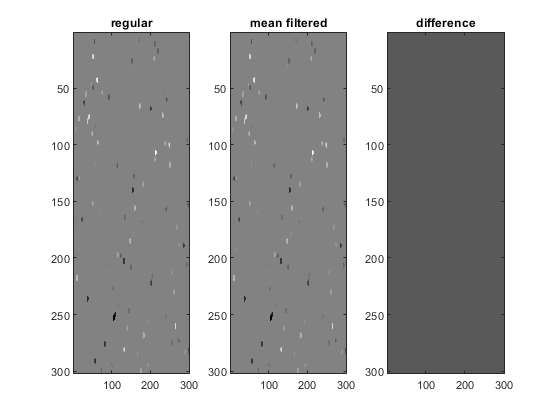

img = importdata("medfilt_problem_dat.mat");
img_med1 = medfilt_3x3(img);
img_med2 = medfilt2(img);
img_med_diff = img_med1 - img_med2;
subplot(1,3,1);
imagesc(img_med1)
colormap('gray')
title('regular')
subplot(1,3,2);
imagesc(img_med2)
title('mean filtered')
colormap('gray')
subplot(1,3,3);
imagesc(img_med_diff)
colormap('gray')
title('difference')

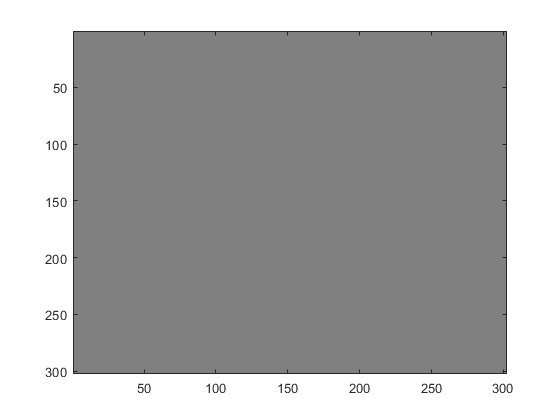

cla();
clf();
imagesc(medfilt2(img, [11,11]))

img_eye = imread('img_001.ppm');


function res = medfilt_3x3(img)
    
    res = zeros(size(img));
    for i=2:length(img(:,1))-1
        for j=2:length(img(1,:))-1
            res(i,j) = median(img(i-1:i+1, j-1:j+1), 'all');
        end
    end
    
end